# PreLab 8

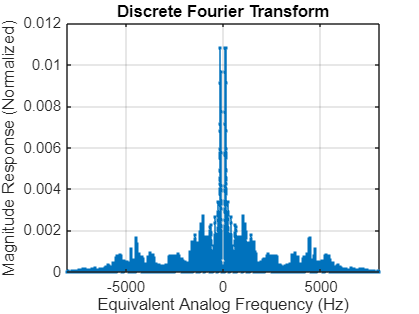

%find peaks frequency
[tea, Ftea] = audioread("tea.wav");
FT(tea, Ftea);

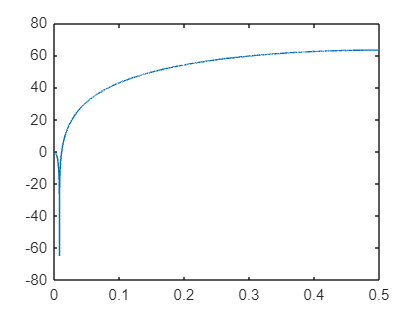

Fo = 133.5/Ftea;

F = linspace(0, 0.5, 10000);
Z = exp(-j*2*pi*F);
HZ = 367.77 - 734.55*exp(-j*2*pi*F) + 367.78*exp(-j*2*pi*F*2);
plot(F, 20*log10(abs(HZ)))

## First FIR filter based off notch

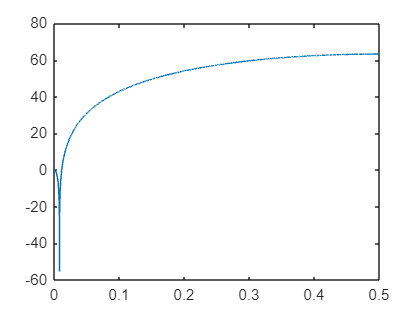


h11c = {[367.77, -734.44, 367.78], [1, 0, 0]};
h21c = {[4.5393 -9.0661 4.5393], [1 -1.7975 0.8100]};
h22c = {[1.1256 -2.2481 1.1256], [1 -1.9573 0.9604]};
h23c = {[1.0264 -2.0500 1.0264], [1 -1.9773 0.9801]};

teaFilt11 = filter([367.77, -734.44, 367.78], [1, 0, 0], tea);
teaFilt21 = filter([4.5393 -9.0661 4.5393], [1 -1.7975 0.8100], tea);
teaFilt22 = filter([1.1256 -2.2481 1.1256], [1 -1.9573 0.9604], tea);
teaFilt23 = filter([1.0264 -2.0500 1.0264], [1 -1.9773 0.9801], tea);

[FFTtea,FSpecTea,FDigTea] = FT(tea, Ftea, "noPlot" );
[FFTteafilt11,FSpecTeafilt11,FDigTeafilt11] = FT(teaFilt11, Ftea, "noPlot");
[FFTteafilt21,FSpecTeafilt21,FDigTeafilt21] = FT(teaFilt21, Ftea, "noPlot");
[FFTteafilt22,FSpecTeafilt22,FDigTeafilt22] = FT(teaFilt22, Ftea, "noPlot");
[FFTteafilt23,FSpecTeafilt23,FDigTeafilt23] = FT(teaFilt23, Ftea, "noPlot");


p = 0;
w = 2*pi*133.5/16000;
D = (p^2 - 2*p*cos(w)+1)/(2-2*cos(w));
HZ2 = D*(Z.^2 - 2.*Z*cos(w)+1)./(Z.^2-2*p.*Z*cos(w)+p^2);
h = {[D, - 2*D*cos(w), D], [1, -2*p*cos(w), p^2]};


plot(F, 20*log10(abs(HZ2)));

%Real poles:

p = 0.75;
D3 = (1 - (p+.99) + 0.99*p ) / (2-2*cos(w));
HZ3 = D3*(Z.^2 - 2.*Z*cos(w)+1)./(Z.^2-Z*(p+0.99)+p*0.99);
h = {[D3, - 2*D3*cos(w), D3], [1, -(p+0.99), p*0.99]};


teaFilt31 = filter(h{1}, h{2}, tea);
sound(teaFilt31, Ftea);

[FFTteafilt31,FSpecTeafilt31,FDigTeafilt31] = FT(teaFilt31, Ftea, "noPlot");



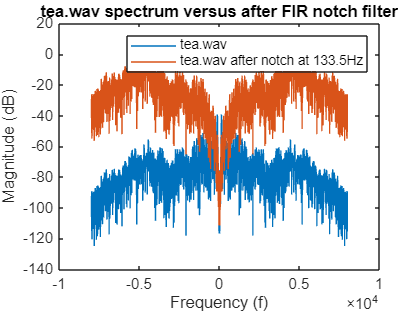

%plots:
%1: spectra before/after notch
newplot;
figure;
plot(FSpecTea, 20*log10(abs(FFTtea)));
hold on;
plot(FSpecTeafilt11, 20*log10(abs(FFTteafilt11)));
title("tea.wav spectrum versus after FIR notch filter");
legend("tea.wav", "tea.wav after notch at 133.5Hz");
xlabel ("Frequency (f)");
ylabel ("Magnitude (dB)");

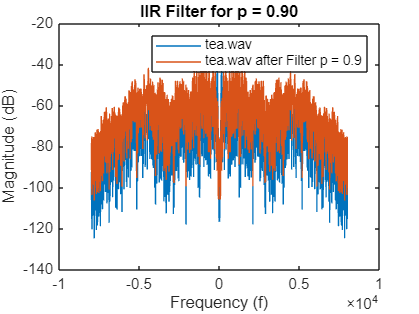


%2: p = 0.9
figure; 
plot(FSpecTea, 20*log10(abs(FFTtea)));
hold on;
plot(FSpecTeafilt21, 20*log10(abs(FFTteafilt21)));
legend("tea.wav", "tea.wav after Filter p = 0.9");
title("IIR Filter for p = 0.90");
xlabel ("Frequency (f)");
ylabel ("Magnitude (dB)");

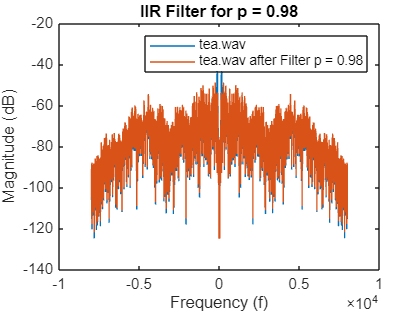

%2: p = 0.98
figure; 
plot(FSpecTea, 20*log10(abs(FFTtea)));
hold on;
plot(FSpecTeafilt22, 20*log10(abs(FFTteafilt22)));
legend("tea.wav", "tea.wav after Filter p = 0.98");
title("IIR Filter for p = 0.98");
xlabel ("Frequency (f)");
ylabel ("Magnitude (dB)");

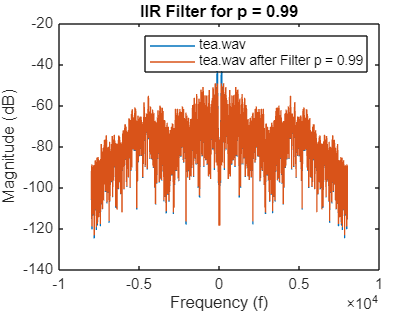

%2: p = 0.99
figure; 
plot(FSpecTea, 20*log10(abs(FFTtea)));
hold on;
plot(FSpecTeafilt23, 20*log10(abs(FFTteafilt23)));
legend("tea.wav", "tea.wav after Filter p = 0.99");
title("IIR Filter for p = 0.99");
xlabel ("Frequency (f)");
ylabel ("Magnitude (dB)");

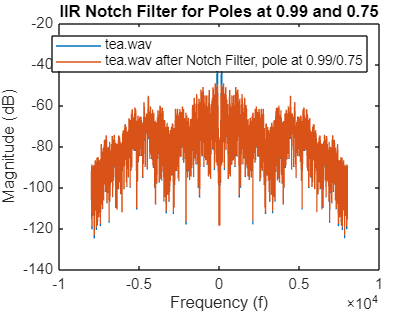



%3: pole = 0.99, 0.75
figure; 
plot(FSpecTea, 20*log10(abs(FFTtea)));
hold on;
plot(FSpecTeafilt23, 20*log10(abs(FFTteafilt23)));
legend("tea.wav", "tea.wav after Notch Filter, pole at 0.99/0.75");
title("IIR Notch Filter for Poles at 0.99 and 0.75");
xlabel ("Frequency (f)");
ylabel ("Magnitude (dB)");